# Lactose Utilization Network of *Escherichia Coli *

% ensure that this is >10 for beta_g to be valid.
% concentrations are expressed in uM.

consts.glu = 50;
consts.tmg_e = 80;

% total LacI conc.
consts.rT = 0.4e-3;

% model params.
params.rho = 167.1;
params.beta_g = 65;
params.n = 2;

**Solve the system of ODEs.**

% time duration.
consts.tmax = 200;

% initial Cdk1 and Cyclin concentrations are 0.
consts.y_init = [0; 0];

% get ODE functions.
ode_funcs = lac_system_ode;

% solve ODE.
[ode_tout, x] = ode45(@(t,y) ode_funcs.dydt(t, y, consts, params), [0; consts.tmax], consts.y_init);

**Unpack and Plot the ODE solutions.**

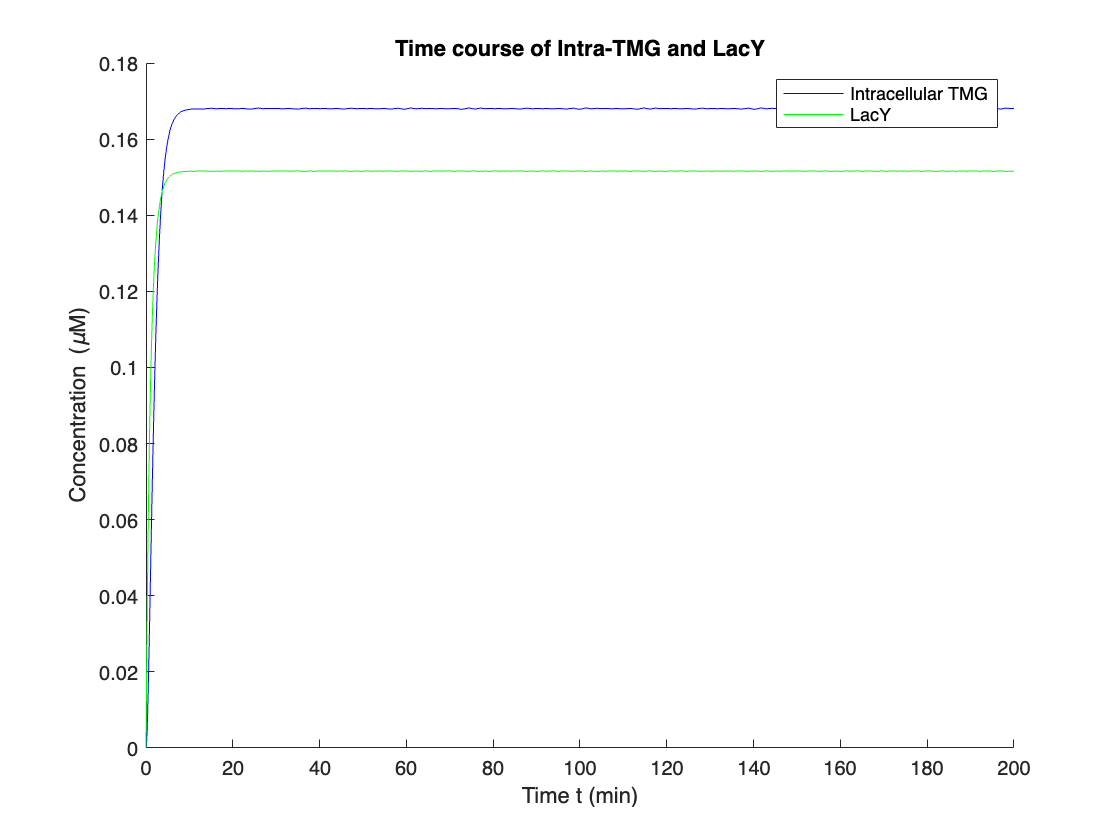

% unpack.
ode_tmgi = x(:, 1);
ode_lacy = x(:, 2);
% plot.
figure; hold on; zoom on;
plot(ode_tout, ode_tmgi, 'Color', 'blue');
plot(ode_tout, ode_lacy, 'Color', 'green');
title('Time course of Intra-TMG and LacY');
xlabel('Time t (min)');
ylabel('Concentration (\muM)');
legend('Intracellular TMG', 'LacY');